%% Feature Selection for 7-Channel Bandpower SVM
% This script:
% 1. Loads the seven-channel EEG epochs
% 2. Extracts the same 14 mu and beta features
% 3. Splits data into training, validation and testing sets
% 4. Ranks features using permutation importance
% 5. Tests models using 4, 6, 8 and 10 features
% 6. Evaluates the best reduced model on the final test set

clear;
close all;
clc;

%% Step 1: Set the project path

basePath = '/Users/kandulasatwika/Desktop/400_BCI_MATLAB';


%% Step 2: Load seven-channel epoch data

load(fullfile(basePath, 'Outputs', 'Filtered data', ...
    'combined_epochs_7channels.mat'));

disp('Seven-channel epoch data loaded.');

Seven-channel epoch data loaded.



disp(['Left shape:  ', mat2str(size(all_left))]);

Left shape:  [7 640 230]


disp(['Right shape: ', mat2str(size(all_right))]);

Right shape: [7 640 220]


disp(['Rest shape:  ', mat2str(size(all_rest))]);

Rest shape:  [7 640 420]




%% Step 3: Balance the three classes

numberOfEpochs = min([size(all_left,3), ...
                      size(all_right,3), ...
                      size(all_rest,3)]);

fprintf('Balanced epochs per class: %d\n', numberOfEpochs);

Balanced epochs per class: 220



rng(42);

leftIndices = randperm(size(all_left,3), numberOfEpochs);

rightIndices = randperm(size(all_right,3), numberOfEpochs);

restIndices = randperm(size(all_rest,3), numberOfEpochs);

leftData = all_left(:,:,leftIndices);

rightData = all_right(:,:,rightIndices);

restData = all_rest(:,:,restIndices);


%% Step 4: Extract the 14 bandpower features

featuresLeft = extract_motor_bandpower( ...
    leftData, samplingRate);

featuresRight = extract_motor_bandpower( ...
    rightData, samplingRate);

featuresRest = extract_motor_bandpower( ...
    restData, samplingRate);


%% Step 5: Create feature names

cleanChannelNames = regexprep( ...
    string(selectedChannels), '\.', '');

numberOfChannels = length(cleanChannelNames);

featureNames = strings(1, numberOfChannels * 2);

for c = 1:numberOfChannels

    featureNames(2*c - 1) = ...
        cleanChannelNames(c) + "_mu";

    featureNames(2*c) = ...
        cleanChannelNames(c) + "_beta";

end

disp('All 14 features:');

All 14 features:


disp(featureNames');

    "FC3_mu"
    "FC3_beta"
    "C3_mu"
    "C3_beta"
    "CP3_mu"
    "CP3_beta"
    "Cz_mu"
    "Cz_beta"
    "FC4_mu"
    "FC4_beta"
    "C4_mu"
    "C4_beta"
    "CP4_mu"
    "CP4_beta"





%% Step 6: Combine features and labels

X = [featuresLeft;
     featuresRight;
     featuresRest];

Y = [repmat("LEFT", numberOfEpochs, 1);
     repmat("RIGHT", numberOfEpochs, 1);
     repmat("REST", numberOfEpochs, 1)];

Y = categorical(Y);

fprintf('Feature matrix shape: %d × %d\n', ...
    size(X,1), size(X,2));

Feature matrix shape: 660 × 14




%% Step 7: Create the final test set

% Keep 20% of the data completely separate.
% This test data will only be used at the end.

cvTest = cvpartition(Y, ...
    'HoldOut', 0.20);

trainValidationMask = training(cvTest);

testMask = test(cvTest);

XTrainValidation = X(trainValidationMask,:);

YTrainValidation = Y(trainValidationMask);

XTest = X(testMask,:);

YTest = Y(testMask);


%% Step 8: Split training and validation data

% Twenty-five per cent of the remaining 80% becomes validation data.
%
% Final approximate split:
% Training   = 60%
% Validation = 20%
% Testing    = 20%

cvValidation = cvpartition( ...
    YTrainValidation, ...
    'HoldOut', 0.25);

trainingMask = training(cvValidation);

validationMask = test(cvValidation);

XTrain = XTrainValidation(trainingMask,:);

YTrain = YTrainValidation(trainingMask);

XValidation = XTrainValidation(validationMask,:);

YValidation = YTrainValidation(validationMask);

fprintf('Training samples:   %d\n', size(XTrain,1));

Training samples:   396



fprintf('Validation samples: %d\n', size(XValidation,1));

Validation samples: 132



fprintf('Testing samples:    %d\n', size(XTest,1));

Testing samples:    132




%% Step 9: Train the original 14-feature model

svmTemplate = templateSVM( ...
    'KernelFunction', 'linear', ...
    'Standardize', true);

fullTrainingModel = fitcecoc( ...
    XTrain, ...
    YTrain, ...
    'Learners', svmTemplate, ...
    'Coding', 'onevsone');

validationPrediction = predict( ...
    fullTrainingModel, XValidation);

baselineValidationAccuracy = mean( ...
    validationPrediction == YValidation);

fprintf('\n14-feature validation accuracy: %.2f%%\n', ...
    baselineValidationAccuracy * 100);


14-feature validation accuracy: 35.61%




%% Step 10: Calculate permutation importance

% Shuffle one feature at a time.
%
% When an important feature is shuffled, model accuracy should decrease.

numberOfFeatures = size(XTrain,2);

numberOfRepeats = 20;

featureImportance = zeros(numberOfFeatures,1);

for f = 1:numberOfFeatures

    accuracyDecrease = zeros(numberOfRepeats,1);

    for repeat = 1:numberOfRepeats

        shuffledValidation = XValidation;

        shuffledRows = randperm( ...
            size(XValidation,1));

        shuffledValidation(:,f) = ...
            shuffledValidation(shuffledRows,f);

        shuffledPrediction = predict( ...
            fullTrainingModel, ...
            shuffledValidation);

        shuffledAccuracy = mean( ...
            shuffledPrediction == YValidation);

        accuracyDecrease(repeat) = ...
            baselineValidationAccuracy - ...
            shuffledAccuracy;

    end

    featureImportance(f) = ...
        mean(accuracyDecrease);

end


%% Step 11: Rank the features

[sortedImportance, rankedFeatureIndices] = ...
    sort(featureImportance, 'descend');

rankedFeatureNames = ...
    featureNames(rankedFeatureIndices);

importanceTable = table( ...
    rankedFeatureNames', ...
    sortedImportance, ...
    rankedFeatureIndices, ...
    'VariableNames', ...
    {'Feature', 'AccuracyDecrease', 'OriginalColumn'});

disp(' ');

disp('=== Ranked Feature Importance ===');

=== Ranked Feature Importance ===



disp(importanceTable);

     Feature      AccuracyDecrease    OriginalColumn
    __________    ________________    ______________

    "FC4_beta"         0.012121             10      
    "CP3_beta"        0.0087121              6      
    "FC4_mu"           0.007197              9      
    "C4_mu"           0.0011364             11      
    "C3_beta"        -0.0049242              4      
    "CP4_beta"        -0.010227             14      
    "C3_mu"            -0.01553              3      
    "FC3_mu"          -0.015909              1      
    "CP4_mu"          -0.018939             13      
    "CP3_mu"          -0.020455              5      
    "C4_beta"         -0.031439             12      
    "Cz_mu"           -0.031818              7      
    "Cz_beta"         -0.045076              8      
    "FC3_beta"        -0.048106              2      



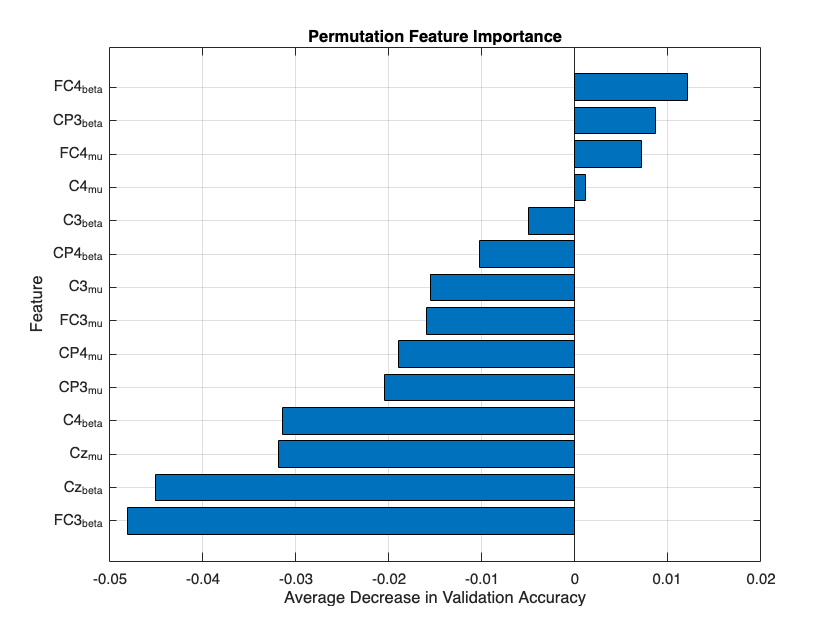



%% Step 12: Plot feature importance

figure;

barh(sortedImportance);

yticks(1:numberOfFeatures);

yticklabels(rankedFeatureNames);

set(gca, 'YDir', 'reverse');

xlabel('Average Decrease in Validation Accuracy');

ylabel('Feature');

title('Permutation Feature Importance');

grid on;



%% Step 13: Test different reduced feature counts

% We already know the full model has 14 features.
% Now compare models containing only the strongest:
%
% 4 features
% 6 features
% 8 features
% 10 features

candidateFeatureCounts = [4, 6, 8, 10];

validationAccuracies = zeros( ...
    length(candidateFeatureCounts), 1);

for kIndex = 1:length(candidateFeatureCounts)

    numberSelected = ...
        candidateFeatureCounts(kIndex);

    selectedColumns = ...
        rankedFeatureIndices(1:numberSelected);

    reducedTrainingData = ...
        XTrain(:,selectedColumns);

    reducedValidationData = ...
        XValidation(:,selectedColumns);

    reducedModel = fitcecoc( ...
        reducedTrainingData, ...
        YTrain, ...
        'Learners', svmTemplate, ...
        'Coding', 'onevsone');

    reducedPrediction = predict( ...
        reducedModel, ...
        reducedValidationData);

    validationAccuracies(kIndex) = mean( ...
        reducedPrediction == YValidation);

    fprintf('%d-feature validation accuracy: %.2f%%\n', ...
        numberSelected, ...
        validationAccuracies(kIndex) * 100);

end

4-feature validation accuracy: 34.85%
6-feature validation accuracy: 37.12%
8-feature validation accuracy: 43.94%
10-feature validation accuracy: 45.45%




%% Step 14: Select the best reduced feature count

% max returns the first result when there is a tie.
% Since the counts are in ascending order, the smaller model wins a tie.

[bestValidationAccuracy, bestPosition] = ...
    max(validationAccuracies);

bestFeatureCount = ...
    candidateFeatureCounts(bestPosition);

selectedFeatureIndices = ...
    rankedFeatureIndices(1:bestFeatureCount);

selectedFeatureNames = ...
    featureNames(selectedFeatureIndices);

disp(' ');

disp('=== Selected Reduced Feature Set ===');

=== Selected Reduced Feature Set ===



fprintf('Best number of features: %d\n', ...
    bestFeatureCount);

Best number of features: 10



fprintf('Best validation accuracy: %.2f%%\n', ...
    bestValidationAccuracy * 100);

Best validation accuracy: 45.45%



disp('Selected features:');

Selected features:



disp(selectedFeatureNames');

    "FC4_beta"
    "CP3_beta"
    "FC4_mu"
    "C4_mu"
    "C3_beta"
    "CP4_beta"
    "C3_mu"
    "FC3_mu"
    "CP4_mu"
    "CP3_mu"





%% Step 15: Train the final reduced model

% Combine training and validation data after feature selection.

XFinalTraining = ...
    XTrainValidation(:,selectedFeatureIndices);

XFinalTest = ...
    XTest(:,selectedFeatureIndices);

finalReducedModel = fitcecoc( ...
    XFinalTraining, ...
    YTrainValidation, ...
    'Learners', svmTemplate, ...
    'Coding', 'onevsone');

finalPrediction = predict( ...
    finalReducedModel, ...
    XFinalTest);

reducedTestAccuracy = mean( ...
    finalPrediction == YTest) * 100;

fprintf('\nFinal reduced-model test accuracy: %.2f%%\n', ...
    reducedTestAccuracy);


Final reduced-model test accuracy: 46.97%




%% Step 16: Train the full 14-feature comparison model

fullComparisonModel = fitcecoc( ...
    XTrainValidation, ...
    YTrainValidation, ...
    'Learners', svmTemplate, ...
    'Coding', 'onevsone');

fullPrediction = predict( ...
    fullComparisonModel, ...
    XTest);

fullTestAccuracy = mean( ...
    fullPrediction == YTest) * 100;

fprintf('Full 14-feature test accuracy: %.2f%%\n', ...
    fullTestAccuracy);

Full 14-feature test accuracy: 45.45%



fprintf('Accuracy difference: %.2f percentage points\n', ...
    reducedTestAccuracy - fullTestAccuracy);

Accuracy difference: 1.52 percentage points


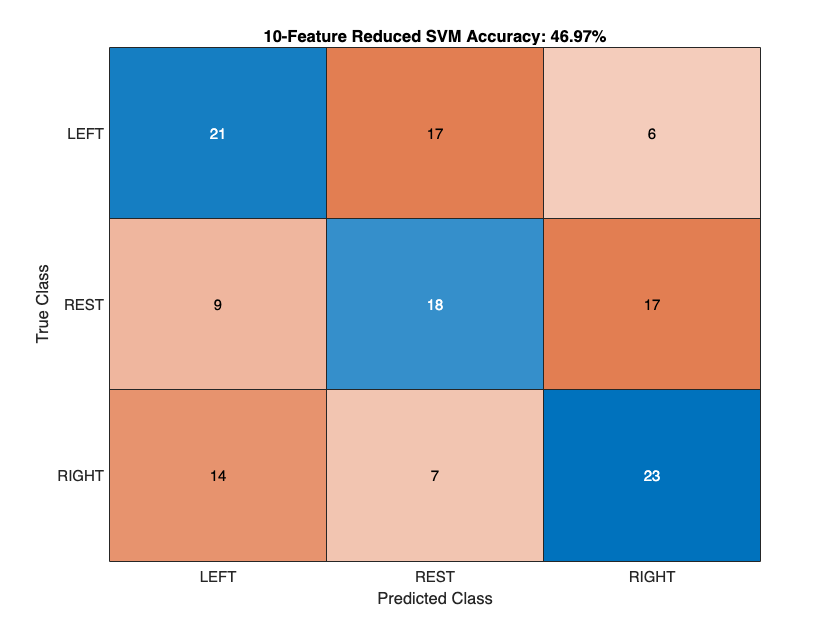



%% Step 17: Display confusion matrix

figure;

confusionchart(YTest, finalPrediction);

title([num2str(bestFeatureCount), ...
    '-Feature Reduced SVM Accuracy: ', ...
    num2str(reducedTestAccuracy, '%.2f'), '%']);



%% Step 18: Display model comparison

comparisonTable = table( ...
    [14; bestFeatureCount], ...
    [fullTestAccuracy; reducedTestAccuracy], ...
    'VariableNames', ...
    {'NumberOfFeatures', 'TestAccuracy'});

disp(' ');

disp('=== Final Model Comparison ===');

=== Final Model Comparison ===



disp(comparisonTable);

    NumberOfFeatures    TestAccuracy
    ________________    ____________

           14              45.455   
           10               46.97   





%% Step 19: Save the reduced model

save(fullfile(basePath, 'Outputs', ...
    'reduced_feature_svm_model.mat'), ...
    'finalReducedModel', ...
    'selectedFeatureIndices', ...
    'selectedFeatureNames', ...
    'bestFeatureCount', ...
    'reducedTestAccuracy', ...
    'fullTestAccuracy', ...
    'featureImportance', ...
    'importanceTable', ...
    'comparisonTable', ...
    'featureNames', ...
    'selectedChannels', ...
    'samplingRate');

disp('Reduced-feature SVM model saved successfully.');

Reduced-feature SVM model saved successfully.




%% Local Function: Extract Mu and Beta Bandpower


function features = extract_motor_bandpower(data, samplingRate)

    % Data shape:
    % channels × time points × epochs

    numberOfChannels = size(data,1);

    numberOfEpochs = size(data,3);

    numberOfFeatures = numberOfChannels * 2;

    features = zeros( ...
        numberOfEpochs, numberOfFeatures);

    for e = 1:numberOfEpochs

        featurePosition = 1;

        for c = 1:numberOfChannels

            signal = double(data(c,:,e));

            [powerSpectrum, frequencies] = ...
                pwelch(signal, [], [], [], samplingRate);

            muPower = mean( ...
                powerSpectrum( ...
                frequencies >= 8 & ...
                frequencies <= 12));

            betaPower = mean( ...
                powerSpectrum( ...
                frequencies >= 13 & ...
                frequencies <= 30));

            features(e,featurePosition) = ...
                log10(muPower + eps);

            features(e,featurePosition + 1) = ...
                log10(betaPower + eps);

            featurePosition = ...
                featurePosition + 2;

        end

    end

end